%% Main File for PnP
clear
% USE MOSEK as solver (ADD to path)
addpath 'C:\Program Files\Mosek\9.3\toolbox\R2015aom'
addpath(genpath(cd));
%% Initial DGU Network
clear
utils = utilityFunctions;
filename = 'config_DGU_1.txt';
[nb_subsystems, Vin,R,L,C, Vmax, Vmin, Imax, Imin] = utils.importData(filename);

Rij_mat = zeros(nb_subsystems);
Rij_mat(1,2) = 1.75; Rij_mat(2,3) = 3.5; Rij_mat(2,4) = 1.75; 
Rij_mat(3,5) = 2.8;
Rij_mat = Rij_mat + tril(Rij_mat',1);
%% Instantiate DGU NETWORK
dguNet = DGU_network(nb_subsystems, Rij_mat);
% references
Vr = linspace(49.95, 50.2, nb_subsystems);
Il = linspace(2.5, 7.5, nb_subsystems);
% set Electrical parameters
for i=1:nb_subsystems
    dguNet = dguNet.initElecParam(i,Vin(i), Vr(i), Il(i), R(i), C(i), L(i), ...
                                  Vmax(i), Vmin(i), Imax(i), Imin(i));
end
dguNet = dguNet.initDynamics([1:1:nb_subsystems]);
%% Test Passivity only: Delta-Formulation of DGU Network
length_sim = 50;
delta_config = true;
dguNet = dguNet.setConstraints(delta_config); % constraints in delta formulation
control_type = "PASSIVITY";
config = "DISTRIBUTED";
[x0, ~, ~] = utils.tuningParam(dguNet, delta_config);
[X,U] = simulate_system(@controller_passivity, x0,length_sim, control_type, dguNet);

Passive controller Gain
   -0.9052   -0.1576

Passive controller Gain
   -0.7093   -0.1826

Passive controller Gain
   -0.7701   -0.1770

Passive controller Gain
   -0.7904   -0.1646

Passive controller Gain
   -0.8460   -0.1592



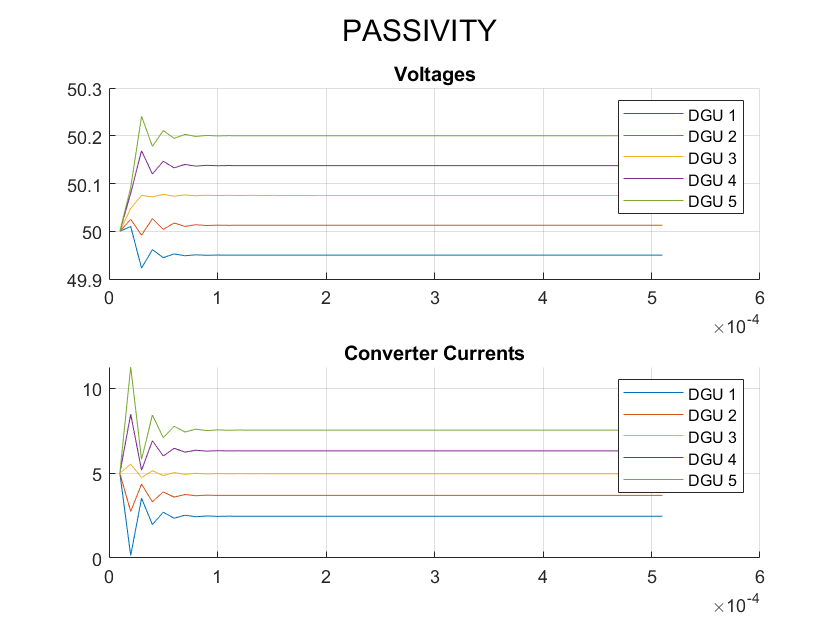

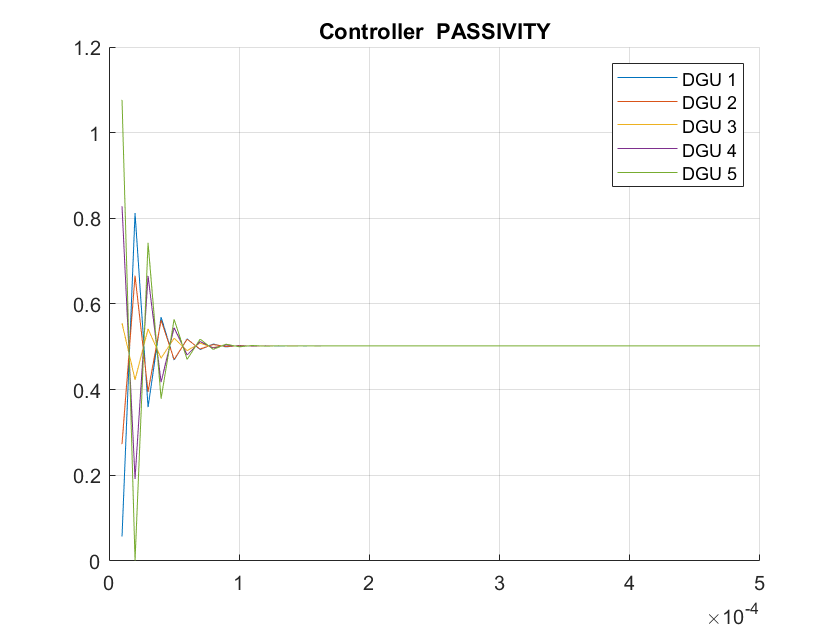

dguNet.plot_DGU_system(X,U, config, control_type, dguNet);


% Compare to LQR
config = "GENERAL";
control_type = 'LQR';
Q = eye(size(dguNet.global_sysd.A,1)); R = eye(size(dguNet.global_sysd.B,2));
[X,U, Pinf] = simulate_system([], x0,length_sim, control_type,...
                        dguNet,Q,R);

LQR controller Gain
   -0.0758   -0.0966    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
    0.0000    0.0000   -0.0821   -0.1097    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000
   -0.0000   -0.0000    0.0000    0.0000   -0.0812   -0.1067   -0.0000   -0.0000    0.0000    0.0000
   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0765   -0.0997    0.0000   -0.0000
   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0753   -0.0970



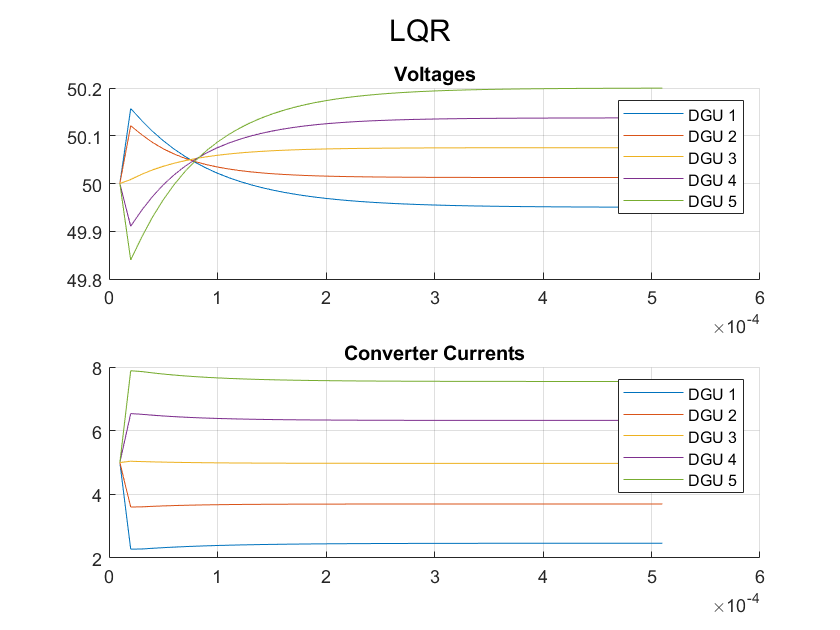

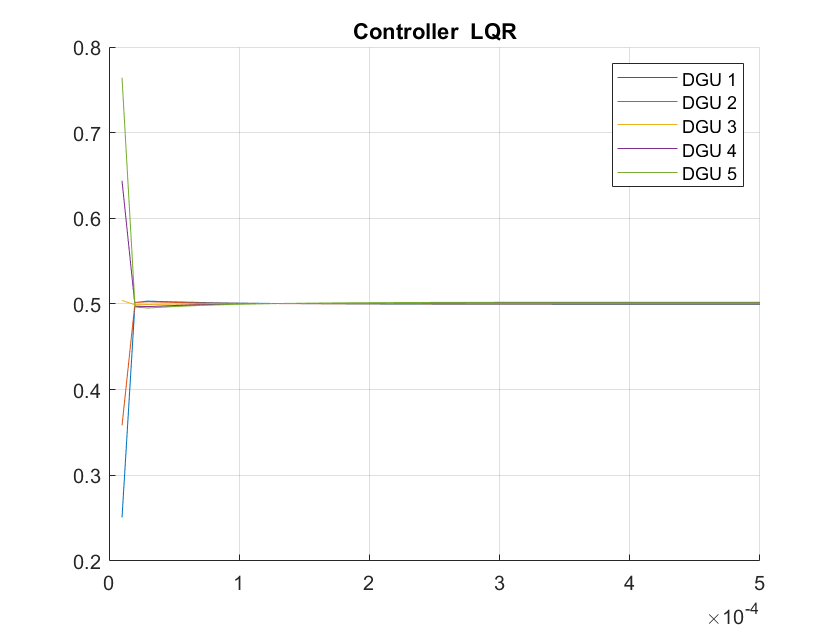

dguNet.plot_DGU_system(X,U, config, control_type, dguNet)

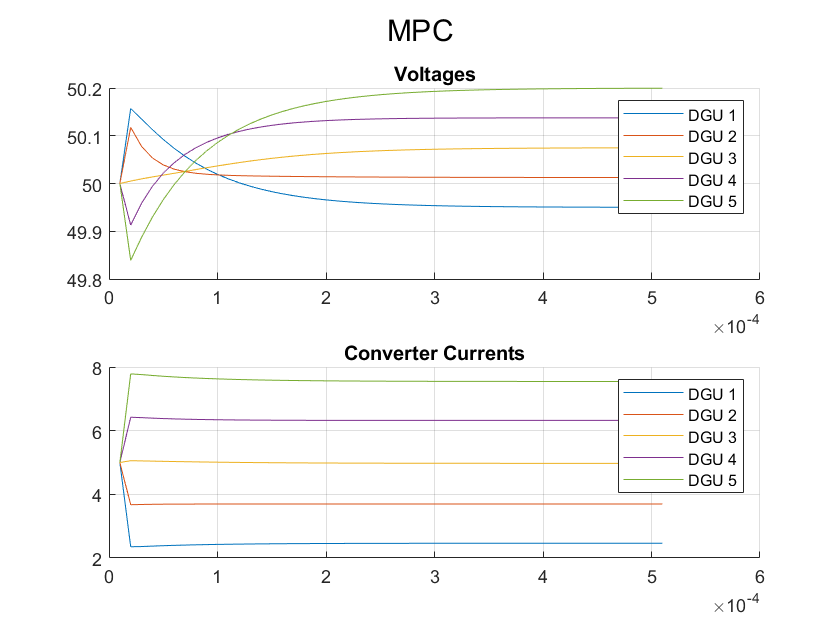

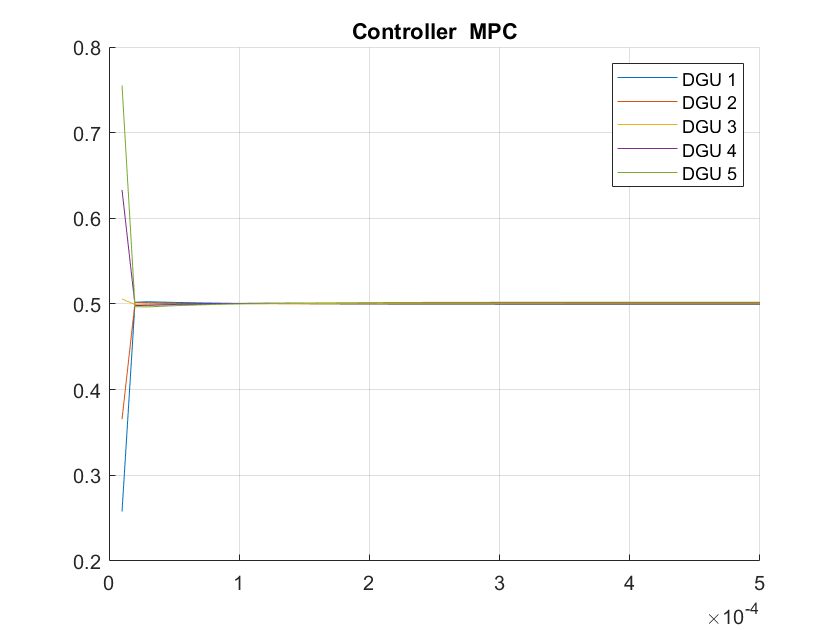

%% Test MPC without reconfigurable terminal ingredients online
use_passivity = false; 
delta_config = true;
[x0, Q_Ni, Ri] = utils.tuningParam(dguNet, delta_config);
dguNet = dguNet.setConstraints(delta_config); % constraints in delta formulation
[P, Gamma_Ni, alpha_i] = offline_distributed_MPC(Q_Ni, Ri, dguNet, ...
                                                  use_passivity);
alpha = zeros(nb_subsystems,1);
 for i=1:nb_subsystems
    alpha(i) = alpha_i; % same alpha for every subsystem in the beginning
 end
 % send to online controller
length_sim = 50;
control_type = "MPC";
[X,U] = simulate_system(@mpc_online, x0,length_sim, control_type, dguNet,...
                         Q_Ni, Ri, P, Gamma_Ni, alpha);
config = "DISTRIBUTED";
dguNet.plot_DGU_system(X,U, config, control_type, dguNet);


%% Test MPC with reconfigurable terminal ingredients online
delta_config = false;
dguNet = dguNet.setConstraints(delta_config);
control_type = "MPC_online";
[x0, Q_Ni, Ri] = utils.tuningParam(dguNet, delta_config);
length_sim = 50;
[X,U] = simulate_system(@mpc_online_2, x0,length_sim, control_type, dguNet,...
                         Q_Ni, Ri);

Passive controller Gain
   -0.9052   -0.1576

Passive controller Gain
   -0.7093   -0.1826

Passive controller Gain
   -0.7701   -0.1770

Passive controller Gain
   -0.7904   -0.1646

Passive controller Gain
   -0.8460   -0.1592



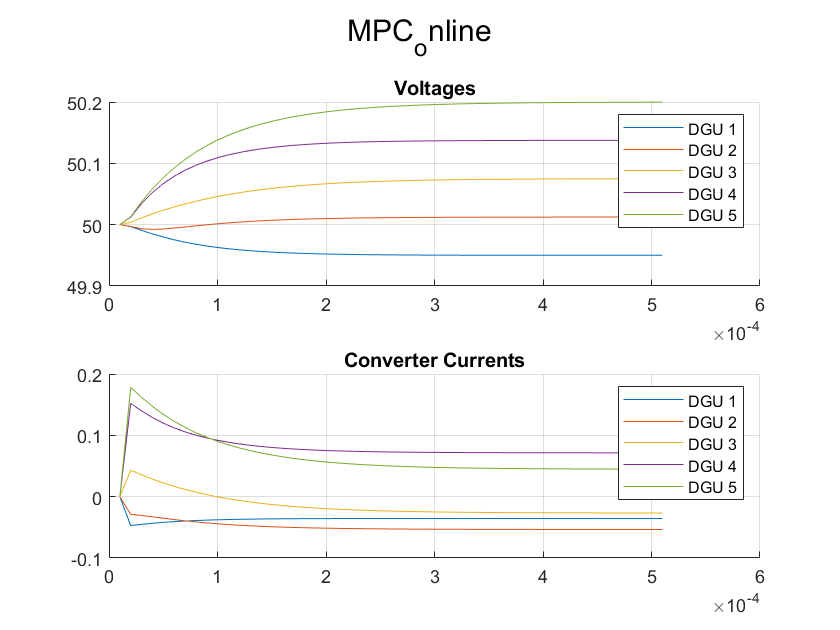

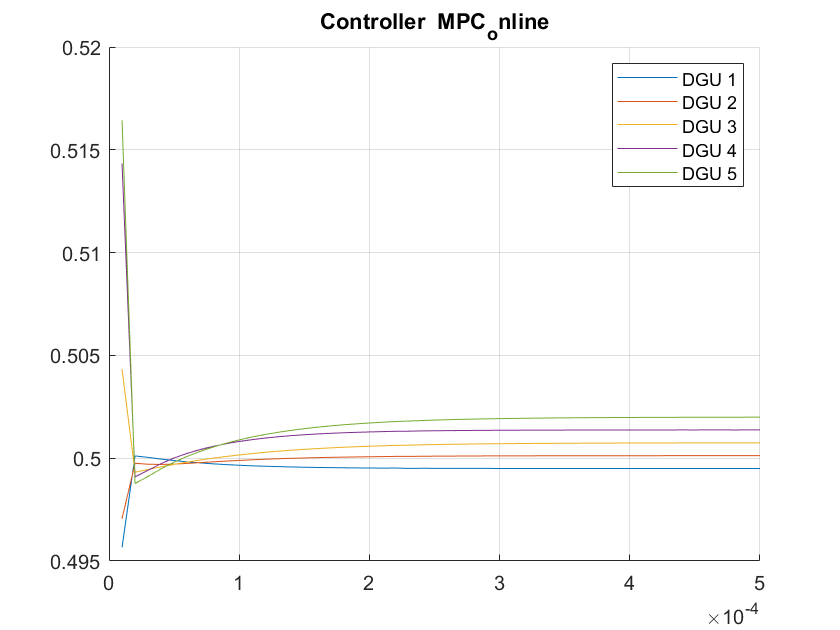

config = "DISTRIBUTED";
dguNet.plot_DGU_system(X,U, config, control_type, dguNet);